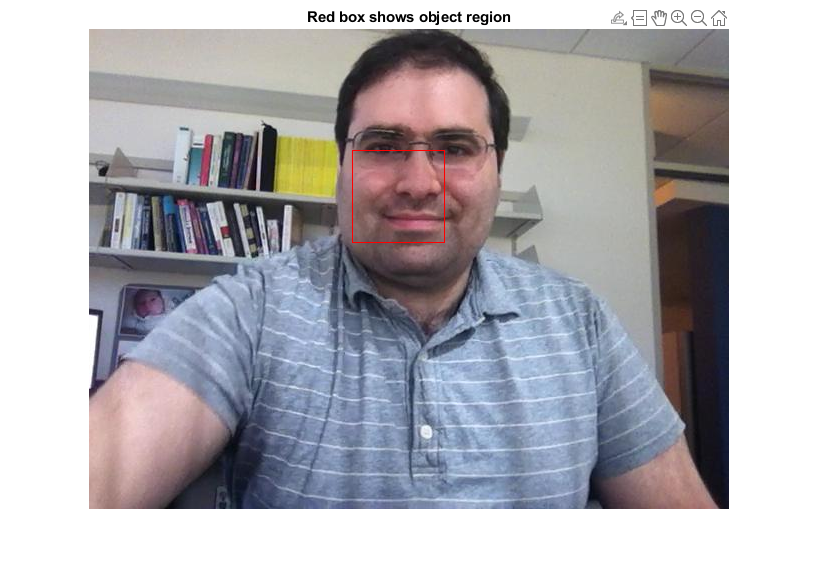

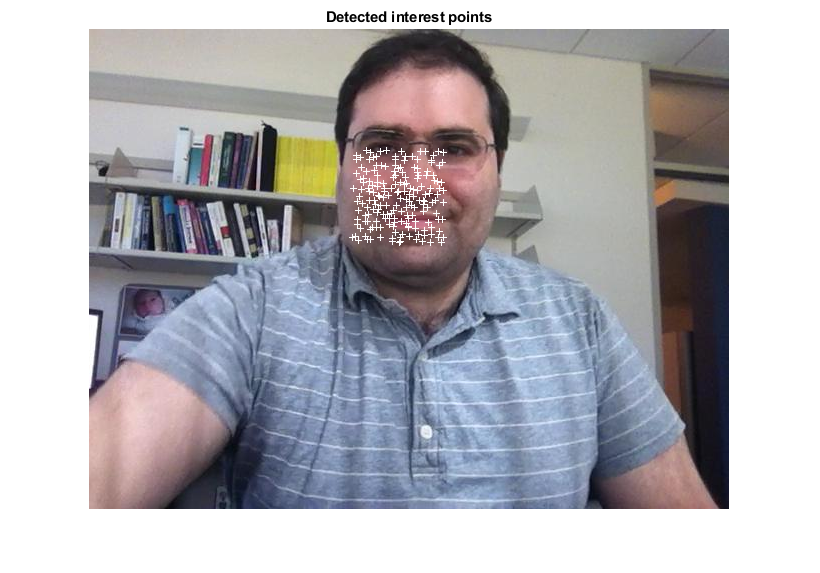

% "face tracking using CamShift algorithm
% Create video reader and player objects
videoFileReader = VideoReader('tilted_face.avi');
videoPlayer = vision.VideoPlayer('Position', [100, 100, 680, 520]);

% Read the first video frame
objectFrame = readFrame(videoFileReader);
objectRegion = [264, 122, 93, 93];

% Show initial frame with a red bounding box.
objectImage = insertShape(objectFrame, 'rectangle', objectRegion, 'Color', 'red');
figure;
imshow(objectImage);
title('Red box shows object region');

% Detect interest points in the object region.
points = detectMinEigenFeatures(im2gray(objectFrame), 'ROI', objectRegion);

% Display the detected points.
pointImage = insertMarker(objectFrame, points.Location, '+', 'Color', 'white');
figure;
imshow(pointImage);
title('Detected interest points');

% Create a point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 1);

% Initialize the tracker.
initialize(pointTracker, points.Location, objectFrame);

% Initialize performance metrics.
total_frames = 0;
total_points = 0;
total_inliers = 0;
num_points_over_time = [];
num_inliers_over_time = [];

% Read, track, display points, and results in each video frame.
while hasFrame(videoFileReader)
    % Read next frame
    frame = readFrame(videoFileReader);
    total_frames = total_frames + 1;
    % Track the points and get their validity
    [points, validity] = pointTracker(frame);

    % Insert markers on the tracked points
    out = insertMarker(frame, points(validity, :), '+');

    % Count total points and inliers over time.
    total_points = total_points + size(points,1);
    total_inliers = total_inliers + sum(validity);
    num_points_over_time(total_frames) = size(points,1);
    num_inliers_over_time(total_frames) = sum(validity);

    % Display the annotated frame using the video player object
    videoPlayer(out);
end

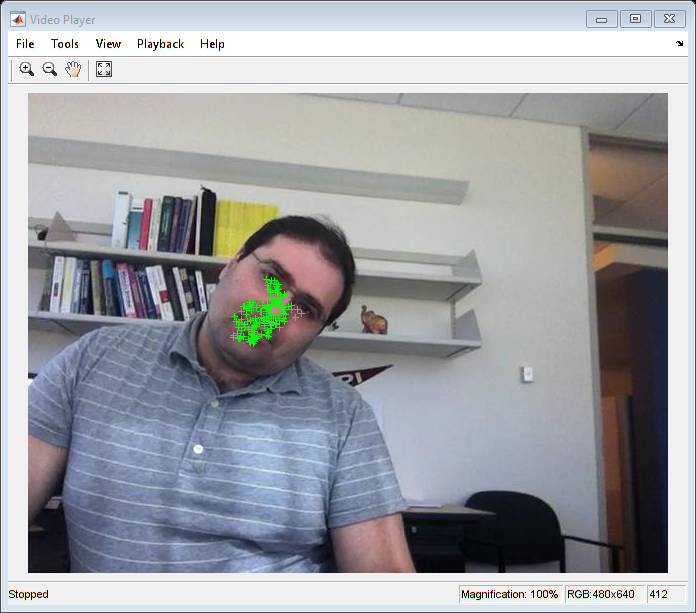


% Release the video player and tracker objects.
release(videoPlayer);

release(pointTracker);

% Calculate and display performance
% Calculate the percentage of tracked points that were inliers.
percent_inliers = total_inliers / total_points * 100;

% Calculate the average number of tracked points per frame.
avg_points_per_frame = total_points / total_frames;

% Display the performance metrics.
fprintf("Percent inliers: %.2f%%\n", percent_inliers);

Percent inliers: 90.72%


fprintf("Average points per frame: %.2f\n", avg_points_per_frame);

Average points per frame: 184.00


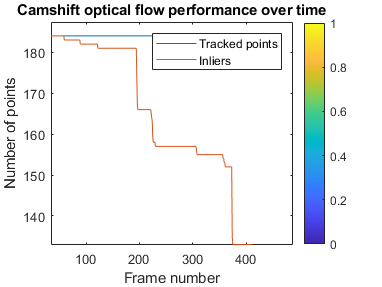


% Plot the number of tracked points and inliers over time.
figure;
plot(num_points_over_time);
hold on;
plot(num_inliers_over_time);
xlabel("Frame number");
ylabel("Number of points");
legend("Tracked points", "Inliers");
title("Camshift optical flow performance over time");

colorbar

xlim([34 488])
ylim([132.9 187.4])


% Display table of results
results = table({'Percent inliers', 'Average points per frame'},...
    {percent_inliers, avg_points_per_frame});
disp(results);

                           Var1                                     Var2         
    ___________________________________________________    ______________________

    {'Percent inliers'}    {'Average points per frame'}    {[90.7213]}    {[184]}




% Calculate performance metrics
avg_points = total_points / total_frames;
avg_inliers = total_inliers / total_frames;

% Display performance metrics in a table
metrics = table(total_frames, total_points, avg_points, total_inliers, avg_inliers);
disp(metrics);

    total_frames    total_points    avg_points    total_inliers    avg_inliers
    ____________    ____________    __________    _____________    ___________

        412            75808           184            68774          166.93   

